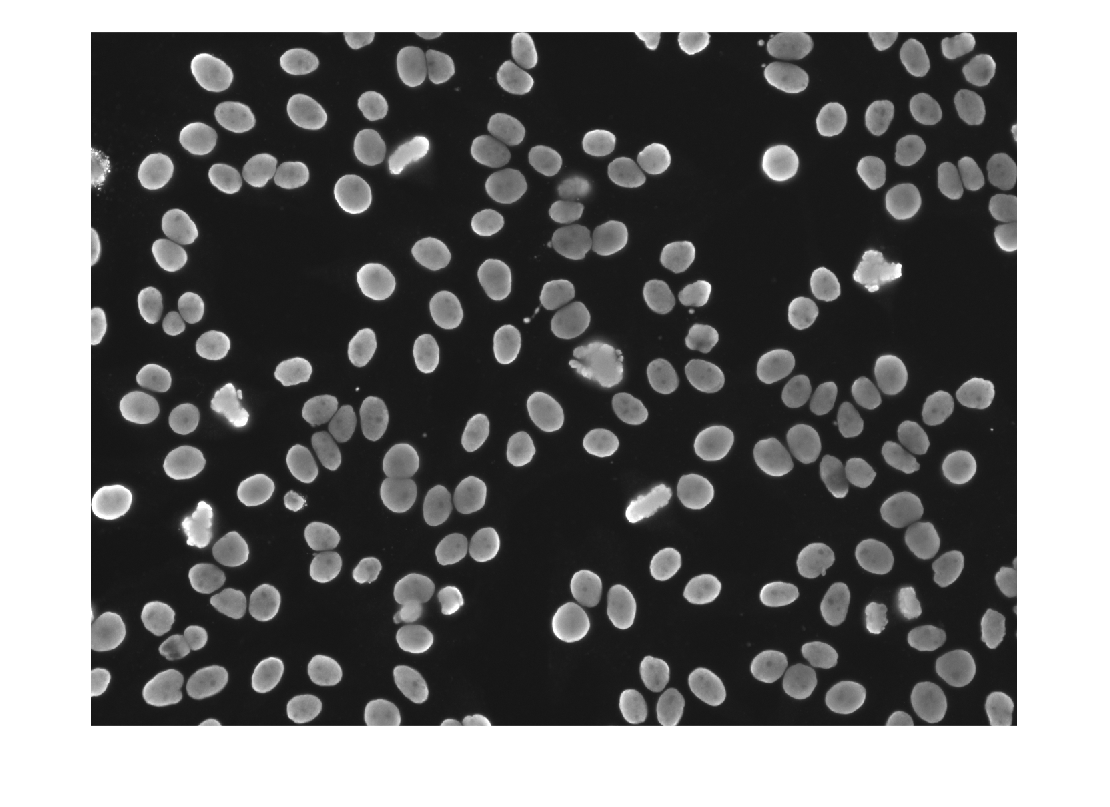

difficulty = 'easy';
fileName = 'hi';
image = imread(sprintf('HEP-2 segmentation/%s/%s_FITC.tif', difficulty, fileName));
comparisonImage = imread(sprintf('HEP-2 segmentation/%s/%s_Mask.tif', difficulty, fileName));
imshow(image);

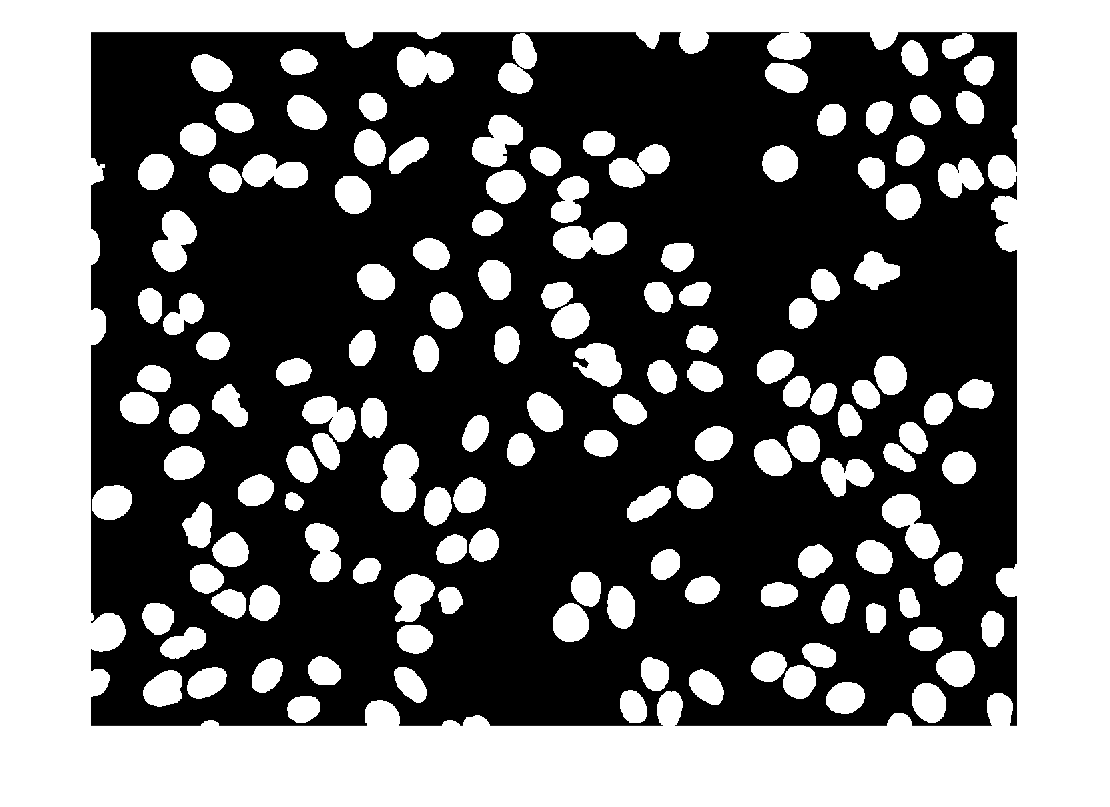

imshow(comparisonImage);

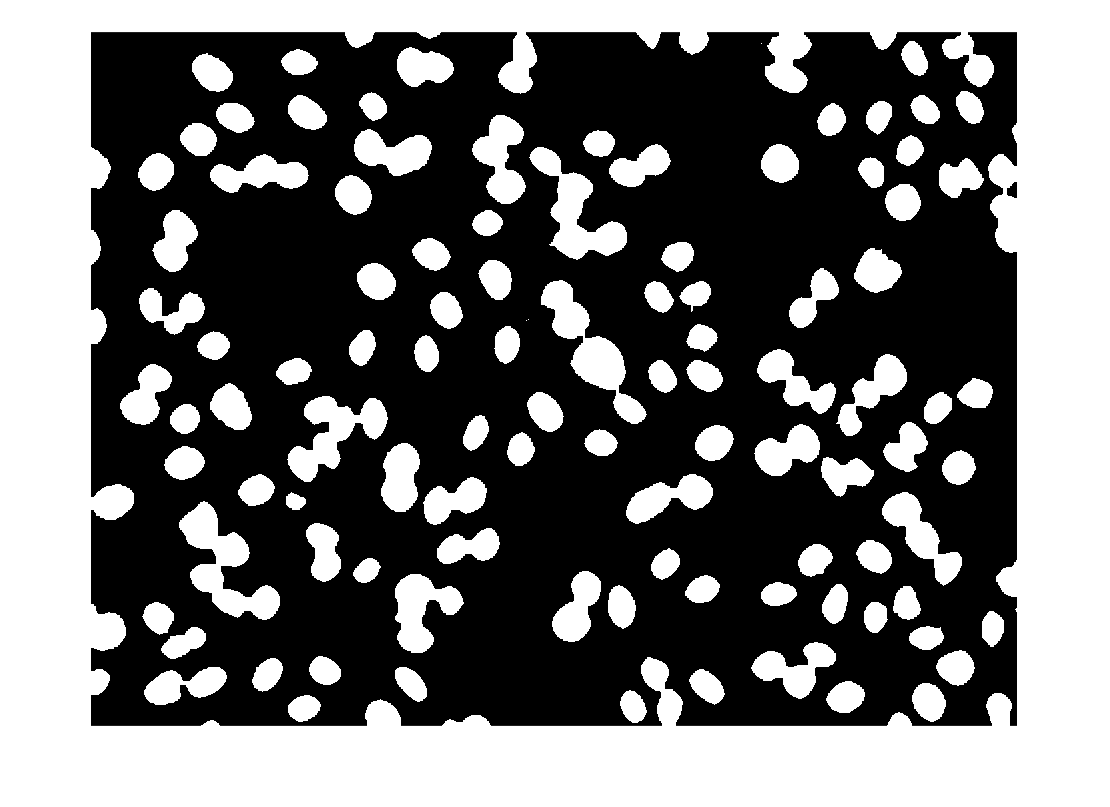

[N,edges] = histcounts(image(:));
[values,locs] = findpeaks(N);

[sortedValues, sortingIndex] = sort(values, 'descend');
sortedLocs = locs(sortingIndex);

topTwo = sortedLocs(1:2);

[minValue, minLocation] = min(N(min(topTwo):max(topTwo)));
threshold = min(topTwo) + minLocation;

histSegmented = image > threshold;
histSegmented = imerode(histSegmented, ones(9));
imshow(histSegmented);

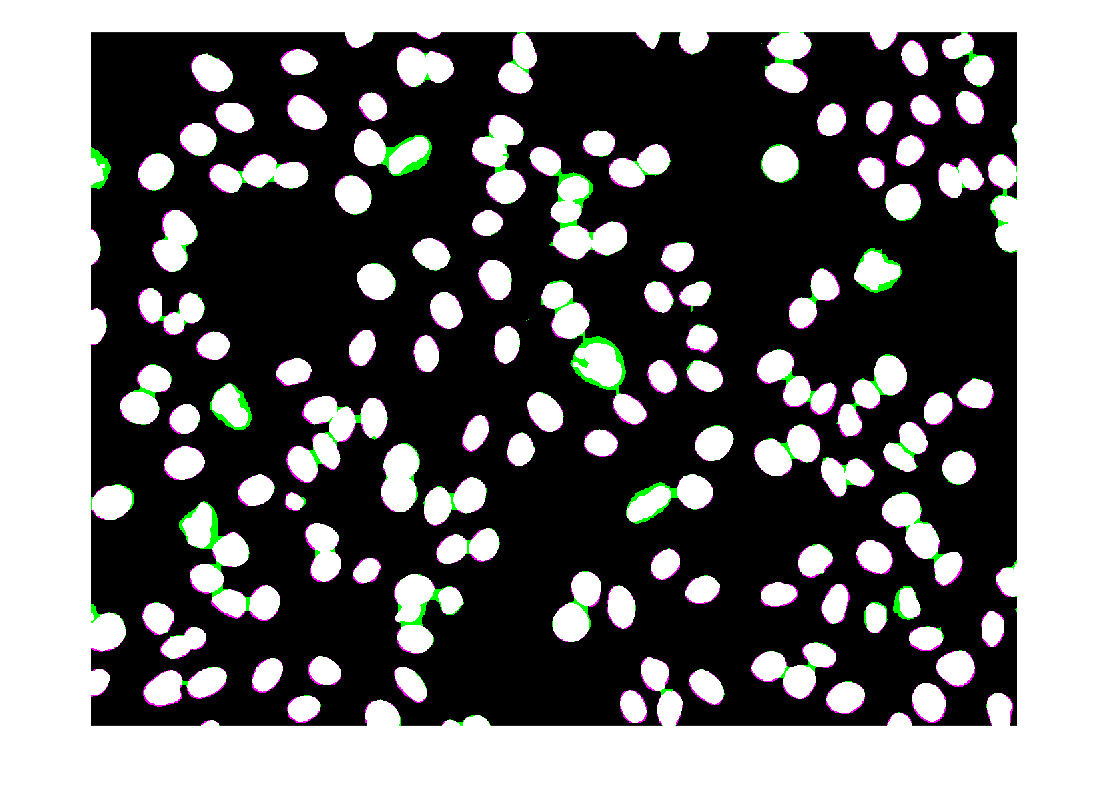

imshowpair(histSegmented, comparisonImage);

histDifference = xor(histSegmented, comparisonImage == 255);
errorPercentage = 100 * sum(histDifference(:)) / (size(histDifference, 1) * size(histDifference, 2))

errorPercentage = 2.5230

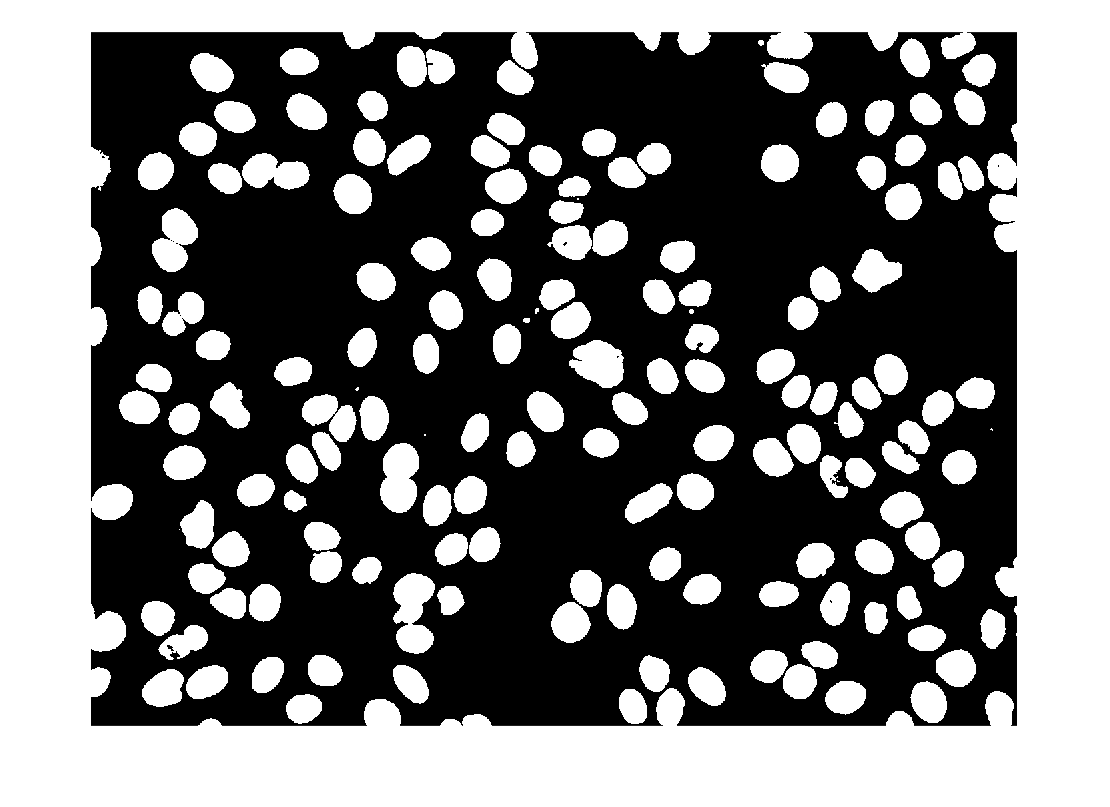

[indexes, centroids] = bwKmeansImage(image, 2);
imshow(indexes);

kmeansDifference = xor(indexes, comparisonImage == 255);
kmeansError = 100 * sum(kmeansDifference(:)) / (size(kmeansDifference, 1) * size(kmeansDifference, 2))

kmeansError = 2.7024

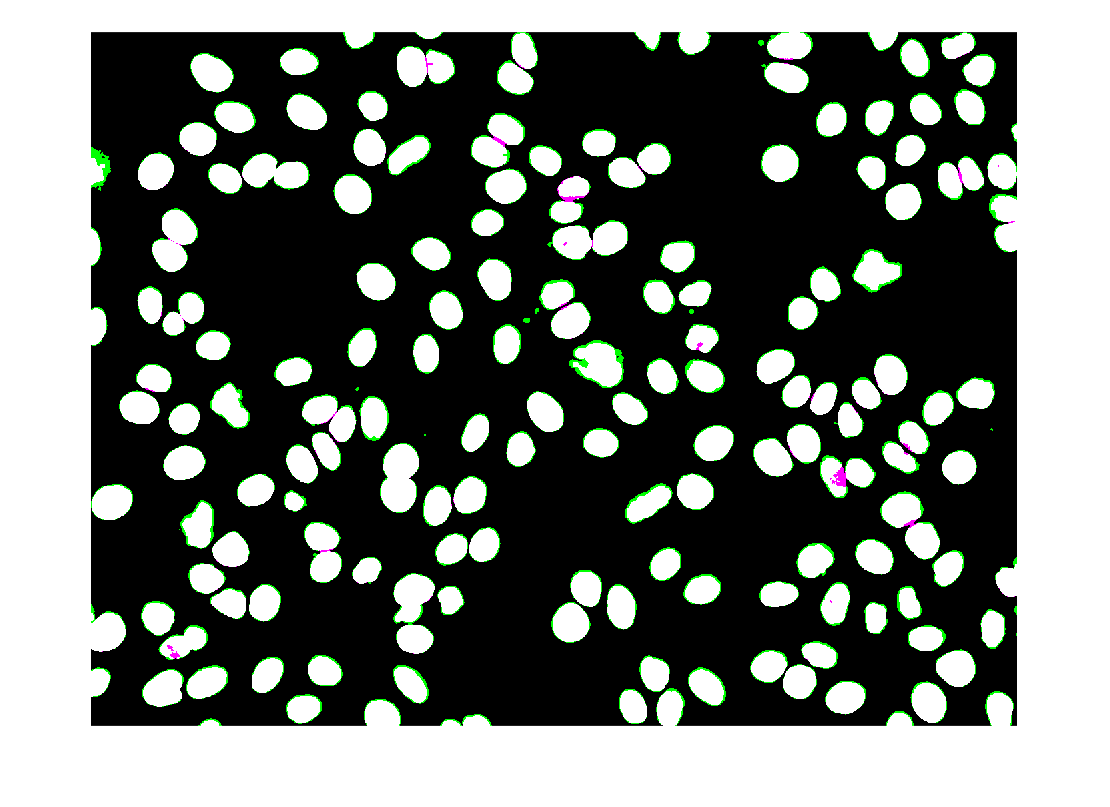

imshowpair(indexes, comparisonImage);

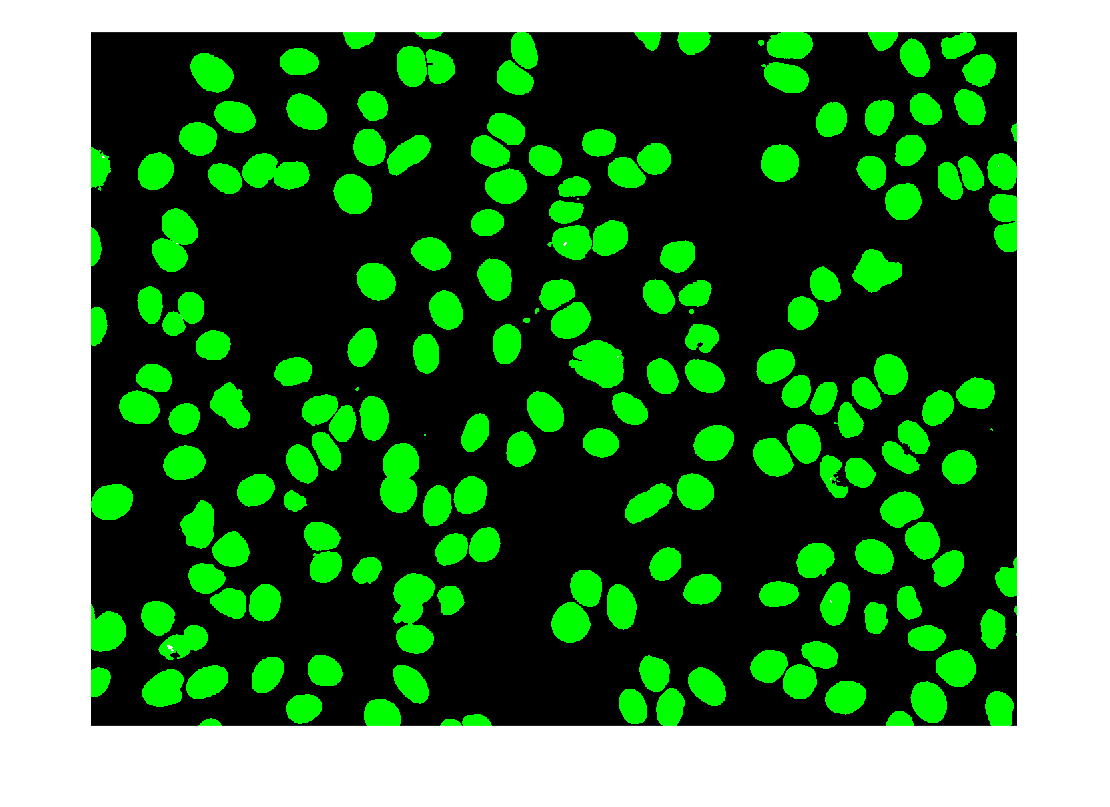

filled = imfill(indexes, 'holes');
imshowpair(filled, filled ~= indexes)

filledDifference = xor(filled, comparisonImage == 255);
filledError = 100 * sum(filledDifference(:)) / (size(filledDifference, 1) * size(filledDifference, 2))

filledError = 2.6968

function [indexes, centroids] = bwKmeansImage(image, k)
    [numRows, numCols] = size(image);
    [classifications, centroids] = kmeans(double(image(:)), k);
    
    indexes = reshape(classifications, numRows, numCols) - 1;
    centroids = uint8(centroids);
    
    if(centroids(1) > centroids(2))
        indexes = ~indexes;
    end
end